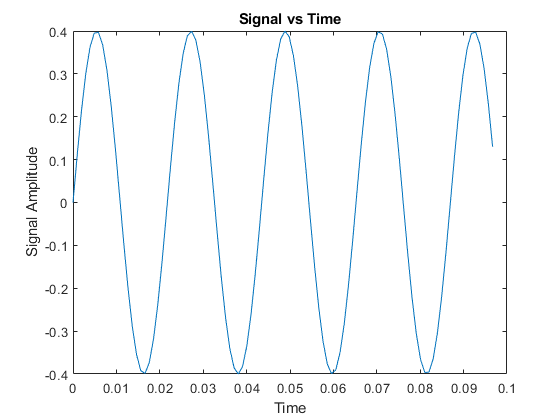

clc; clear all

load('lab04_analysis_signal1.mat')

plot(t(1:100),x(1:100))
xlabel('Time')
ylabel('Signal Amplitude')
title('Signal vs Time')

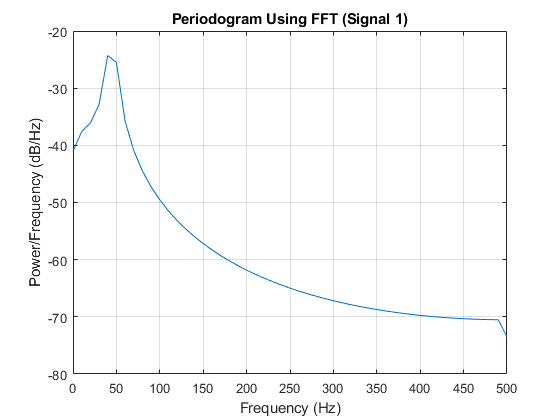


fs = 1000;
% t = 0:1/fs:1-1/fs;
% x = cos(2*pi*50*t) + randn(size(t));

N = length(x(1:100));
xdft = fft(x(1:100));
xdft = xdft(1:N/2+1);
psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x(1:100)):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT (Signal 1)")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")


N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);

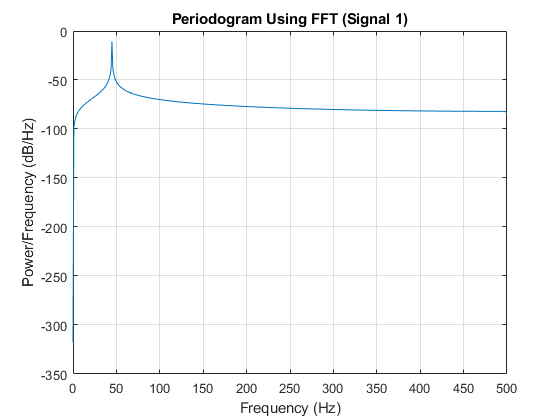

psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT (Signal 1)")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")

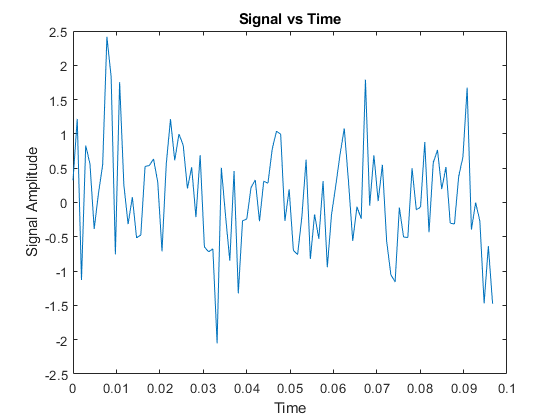


load('lab04_analysis_signal2.mat')

plot(t(1:100),x(1:100))
xlabel('Time')
ylabel('Signal Amplitude')
title('Signal vs Time')

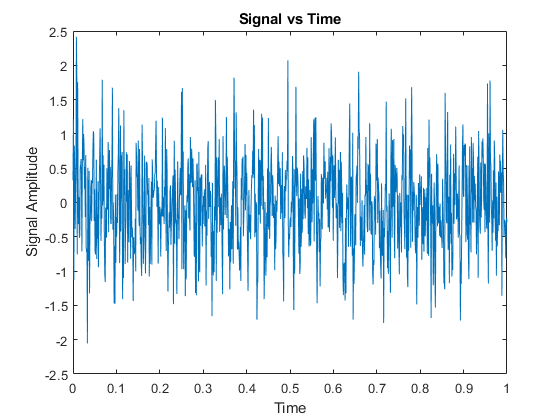


plot(t,x)
xlabel('Time')
ylabel('Signal Amplitude')
title('Signal vs Time')


N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);

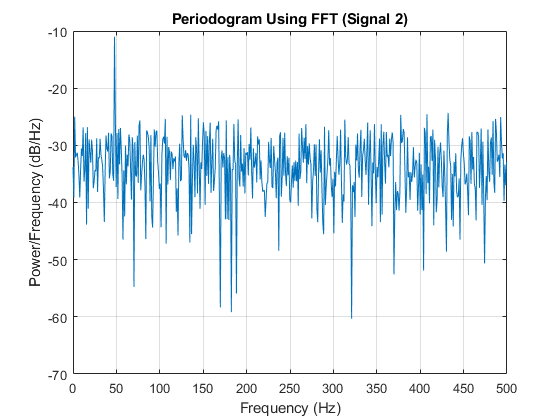

psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT (Signal 2)")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")

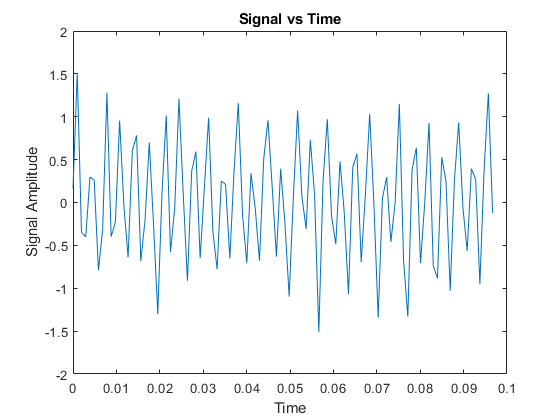


load('lab04_analysis_signal3.mat')

plot(t(1:100),x(1:100))
xlabel('Time')
ylabel('Signal Amplitude')
title('Signal vs Time')

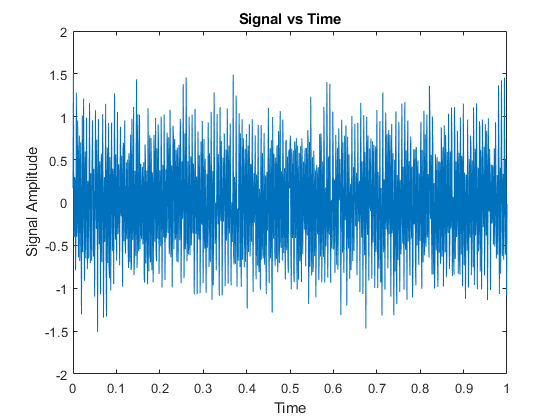


plot(t,x)
xlabel('Time')
ylabel('Signal Amplitude')
title('Signal vs Time')


N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);

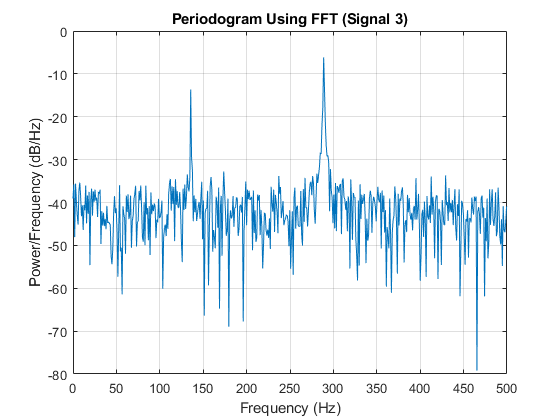

psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT (Signal 3)")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")